## CNN

%% TRAIN CNN ON CLEAN DATA (RGB, 256x256) — train_cnn_clean.mlx
clear; clc;

% DATA
% Paths
rootClean     = 'D:\LocalUser\42177 Project\data\clean';
artifactsDir  = 'D:\LocalUser\42177 Project\artifacts';
evalPath      = 'D:\LocalUser\42177 Project\evaluate_model.mlx';  % updated path
if ~exist(artifactsDir,'dir'), mkdir(artifactsDir); end

% Add the folder (not the .mlx file) to MATLAB path
addpath(fileparts(evalPath));

% Seed for reproducibility
rng(42177);

% Datastores
imdsTrain = imageDatastore(fullfile(rootClean,'train'),"IncludeSubfolders",true,"LabelSource","foldernames");
imdsVal   = imageDatastore(fullfile(rootClean,'val'),  "IncludeSubfolders",true,"LabelSource","foldernames");
imdsTest  = imageDatastore(fullfile(rootClean,'test'), "IncludeSubfolders",true,"LabelSource","foldernames");

classes   = categories(imdsTrain.Labels);
inputSize = [256 256 3];

% Data augmentation
aug = imageDataAugmenter('RandXReflection',true,'RandRotation',[-10 10]);
adsTrain = augmentedImageDatastore(inputSize, imdsTrain, 'DataAugmentation', aug);
adsVal   = augmentedImageDatastore(inputSize, imdsVal);
adsTest  = augmentedImageDatastore(inputSize, imdsTest);


Define the convolutional neural network architecture

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:47 |       21.88% |       66.53% |       2.1333 |       1.3968 |          0.0010 |
|       1 |          50 |       00:10:41 |       90.62% |       89.04% |       0.3949 |       0.3873 |          0.0010 |
|       1 |         100 |       00:18:52 |       95.31% |       92.43% |       0.2157 |       0.2606 |          0.0010 |
|       1 |         150 |       00:26:59 |       95.31% |       94.51% |       0.2242 |       0.2021 |          0.0010 |
|       

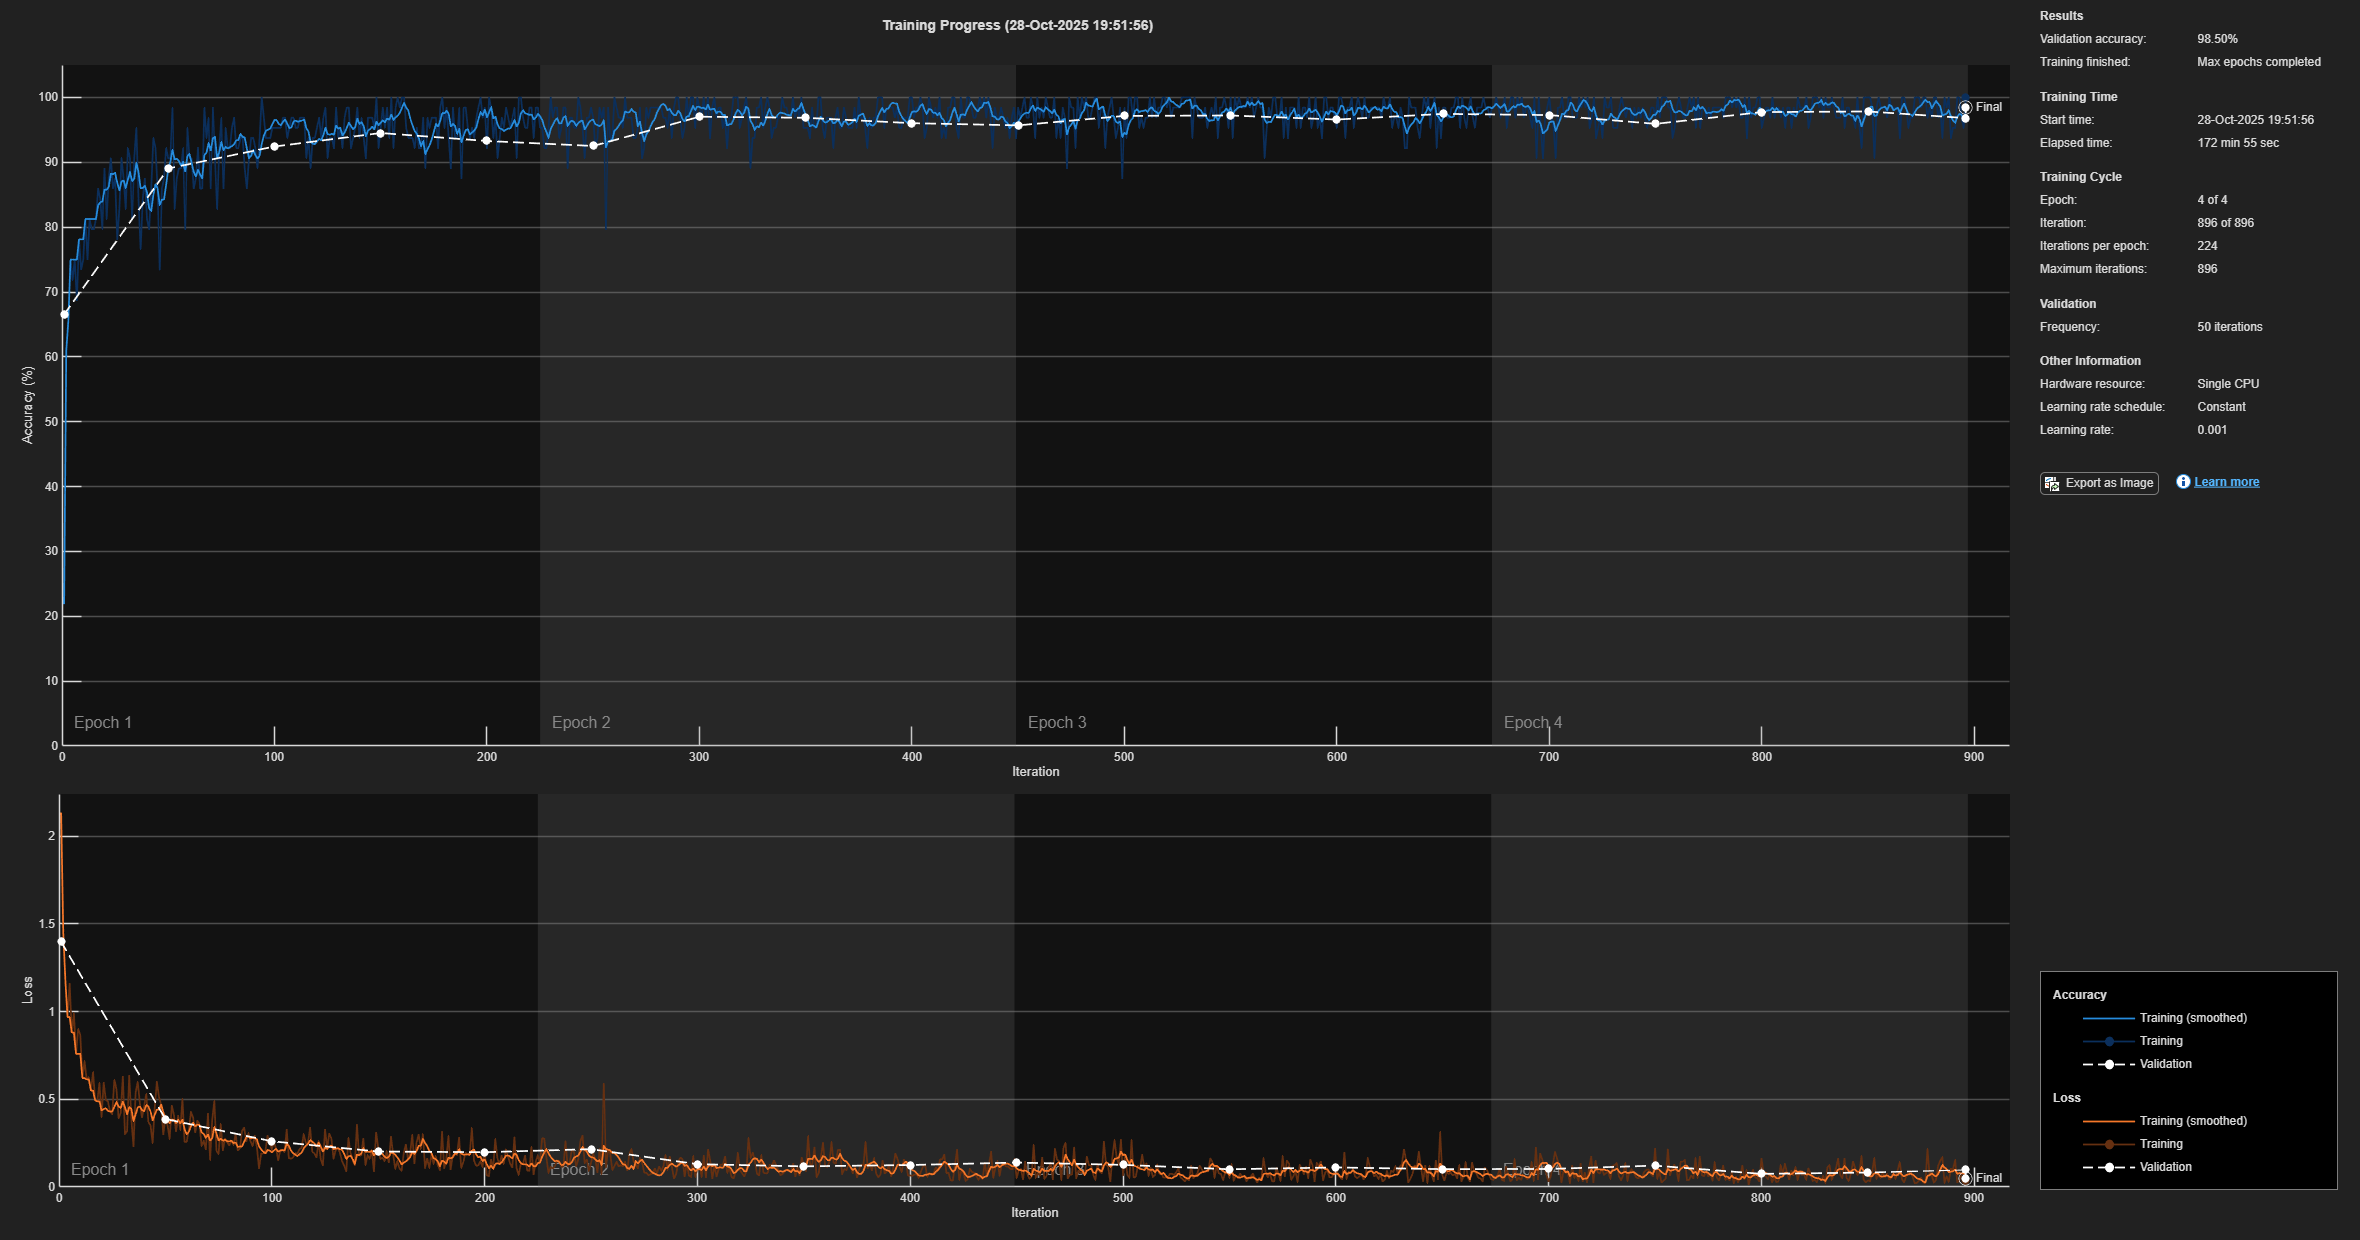

% MODEL
layers = [
    imageInputLayer(inputSize,"Normalization","none")
    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,128,"Padding","same")
    batchNormalizationLayer
    reluLayer

    globalAveragePooling2dLayer
    fullyConnectedLayer(numel(classes))
    softmaxLayer
    classificationLayer
];

% Training options
options = trainingOptions('adam', ...
    'MiniBatchSize',64, ...
    'MaxEpochs',4, ...   % operation compute capacity can only afford 4
    'InitialLearnRate',1e-3, ...
    'ValidationData',adsVal, ...
    'Shuffle','every-epoch', ...
    'Verbose',true, ...
    'Plots','training-progress');

%% Train
t0 = tic;
[net, trainInfo] = trainNetwork(adsTrain, layers, options);

trainSecs = toc(t0);
fprintf('Training time: %.1f min\n', trainSecs/60);

Training time: 190.3 min



% Save model
save(fullfile(artifactsDir,'cnn_model.mat'),'net','classes','trainInfo','trainSecs');


Evaluation

%% Load trained model
load('D:\LocalUser\42177 Project\artifacts\cnn_model.mat','net','classes');

%% Recreate datastores for test set
rootClean = 'D:\LocalUser\42177 Project\data\clean';
imdsTest  = imageDatastore(fullfile(rootClean,'test'),"IncludeSubfolders",true,"LabelSource","foldernames");
adsTest   = augmentedImageDatastore([256 256 3], imdsTest);


%% Evaluate on clean test set
t1 = tic;
[YPred, ~] = classify(net, adsTest);
testSecs = toc(t1);
fprintf('Clean test time: %.1f s\n', testSecs);

Clean test time: 70.7 s



y_true = string(imdsTest.Labels);
y_pred = string(YPred);


% Evaluate model
results = evaluate_model(y_true, y_pred, string(classes));

Accuracy: 98.59%
Precision: 97.64%  Recall: 98.54%  F1: 98.08%


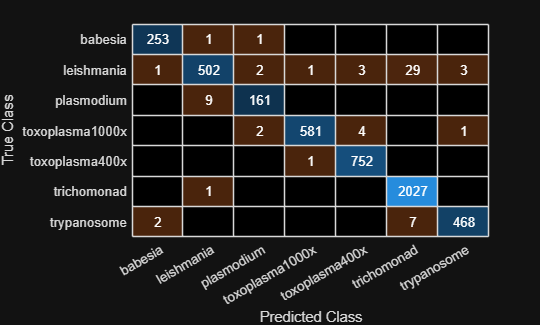


% Save results
artifactsDir  = 'D:\LocalUser\42177 Project\artifacts';
if ~exist(artifactsDir,'dir'), mkdir(artifactsDir); 
end

save(fullfile(artifactsDir,'results_cnn_clean.mat'),'results','testSecs');

%% display confusion matrix:
confusionchart(results.ConfusionMatrix, results.Labels);